# **Práctica 3: Diseño e implementación de Controladores PID**

Las prácticas de la asignatura Control con Computador consisten en el estudio de un servomecanismo de posicionamiento angular (LJ Technical Systems) controlado por un PC. Las sesiones de laboratorio P1 y P2 se centran en el análisis experimental de las respuestas temporal y frecuencial del sistema respectivamente. Las sesiones P3 y P4 se dedican al diseño de controladores PID. Por último, en la práctica P5 se diseñarán controladores en campo frecuencial.

**OBJETIVO: Diseñar un controlador PI de velocidad de salida para que el sistema de lazo cerrado tenga un error estacionario nulo. Diseñar un controlador PID de la posición del eje de salida para la planta estudiada en las sesiones anteriores para que el sistema en lazo cerrado cumpla unas ciertas especificaciones.**

**En esta sesión el estudiante ha de:**

- **Diseñar un PI y un PID por asignación de polos.**

- **Verificar experimentalmente los sistemas de control diseñados.**

% Alternar entre los datos del experimento y los del directorio Resultados
% Si desea usar los datos del directorio Resultados = false
% Si desea usar datos propios = true
useExperimentalData = false;

# Ejercicio 11: Diseño y verificación experimental de un PI por asignación de polos.

Diseñar un PI de control de velocidad que haga que la respuesta temporal a una entrada escalón no presente sobreimpulsos y que el tiempo de establecimiento (con el criterio del 2%) sea de 0.9 segundos. Para la simulación del controlador PI digital, abrir y ejecutar el modelo P3_Ex11a.slx. Para su comprobación con el motor, abrir y ejecutar el modelo P3_Ex11b.slx.

% plant
K0=0.82;
tau0=0.26;

% Sampling time
Ts=0.01;

% Especifications
xi=1;
ts_2=0.9; % settling time with %2 criterion
Tdes=ts_2/4;
wn=5.8/(xi*ts_2);

% Controller design
Zdes=exp(-Ts/Tdes);
alpha=exp(-Ts/tau0);
beta=-2*exp(-Ts*xi*wn)*cos(wn*Ts*sqrt(1-xi^2));
gamma=exp(-2*Ts*xi*wn);

Ki_star=(gamma-alpha+beta+(alpha+1))/(2*K0*(1-alpha));
Ki=(2/Ts)*Ki_star;
Kp=((beta+alpha+1)/(K0*(1-alpha)))-Ki_star;

Para diseñar el controlador, se han seguido los siguientes pasos. Primeramente, se ha digitalizado la planta con un mantenedor de orden cero y se ha escogido un controlador PI discretizado mediante la aproximación trapezoidal.


$$\mathrm{motor}:G\left(z\right)=k_{\mathrm{mot}} \frac{1-\alpha }{z-\alpha }\;\;\;\;\;\;\;\;\;\mathrm{donde}\;\;\;\;\;\;\;\;\;\;\;\;\alpha =e^{-\frac{T_s }{\tau_0 }}$$



$$\mathrm{controlador}\;\mathrm{PI}:\mathrm{PI}\left(z\right)=k_p +k_i \frac{T_s }{2}\frac{z+1}{z-1}=k_p +k_i^* \frac{z+1}{z-1}\;\;\;\;\;\;\mathrm{donde}\;\;\;\;k_i^* =k_i \frac{T_s }{2}$$


Con lo cual la función de transferencia del lazo cerrado:


$$\textrm{l}c\left(z\right)=\frac{\textrm{PI}\left(z\right)G\left(z\right)}{1+\textrm{PI}\left(z\right)G\left(z\right)}=\frac{k_{\mathrm{mot}} \left(k_p +k_i^* \right)\left(z+\frac{k_i^* -k_p }{k_i^* +k_p }\right)\left(1-\alpha \right)}{\left(z-1\right)\left(z-\alpha \right)+k_{\mathrm{mot}} \left(k_p +k_i^* \right)\left(z+\frac{k_i^* -k_p }{k_i^* +k_p }\right)\left(1-\alpha \right)}$$


Igualando la ecuación caracteristica real, con la ideal, podremos sintonizar nuestros parámetros.


$$\begin{array}{l}
\mathrm{eq}\;\mathrm{real}:z^2 +\left\lbrack \left(k_p +k_i^* \right)k_{\mathrm{mot}} \left(1-\alpha \right)-\left(\alpha +1\right)\right\rbrack z+\alpha +k_{\mathrm{mot}} \left(k_i^* -k_p \right)\left(1-\alpha \right)=0\\
\mathrm{eq}\;\mathrm{ideal}:z^2 -2e^{-T_s \xi \omega_n } \mathrm{cos}\left(\omega_n T_s \sqrt{1-\xi^2 }\right)z+e^{-2T_s \xi \omega_n } 
\end{array}$$


Con lo cual, las ecuaciones de sintonía serían:


$$\begin{array}{l}
k_p =\frac{-\left(-2e^{-T_s \xi \omega_n } \mathrm{cos}\left(\omega_n T_s \sqrt{1-\xi^2 }\right)+e^{-2T_s \xi \omega_n } +1\right)}{T_s \;k_{\mathrm{mot}} \;\left(\alpha -1\right)}\\
k_i =\frac{-2e^{-T_s \xi \omega_n } \mathrm{cos}\left(\omega_n T_s \sqrt{1-\xi^2 }\right)+e^{-2T_s \xi \omega_n } +1}{2{\;k}_{\mathrm{mot}} \;\left(\alpha -1\right)}-\frac{\alpha -2e^{-T_s \xi \omega_n } \mathrm{cos}\left(\omega_n T_s \sqrt{1-\xi^2 }\right)+1}{k_{\mathrm{mot}} \;\left(\alpha -1\right)}
\end{array}$$


Las respuestas ideal y real se pueden observar en la siguiente imagen.

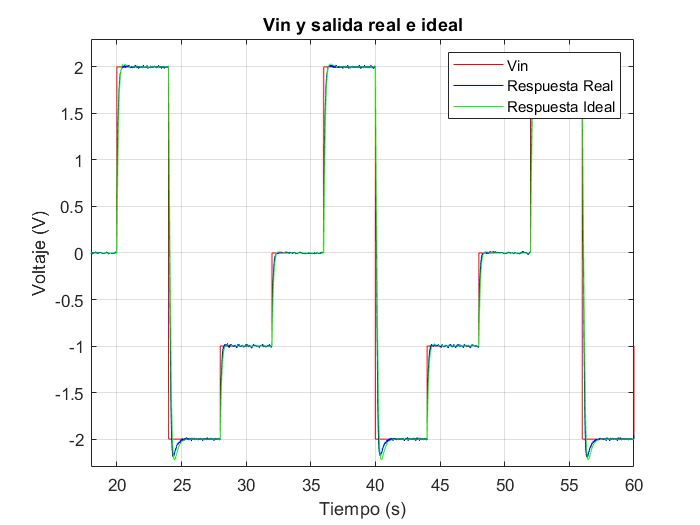

% Dibujar la respuesta del motor
if useExperimentalData
    % Usar Simulink
    addpath([pwd filesep 'PIvel']);
    open PI_experimental.slx;
    run PI_experimental.slx;
else
    FileName   = 'PI_real_experimental.mat';
    cd('..')
    FolderName = [pwd filesep 'Common' filesep 'Resultados' filesep 'Prac3'];
    File       = fullfile(FolderName, FileName);
    load(File);   
end

figure
plot(PI_real_experimental.time,[PI_real_experimental.signals.values(:,1,:)],'r')
hold on; grid on;
plot(PI_real_experimental.time,[PI_real_experimental.signals.values(:,2,:)],'b')
plot(PI_real_experimental.time,[PI_real_experimental.signals.values(:,3,:)],'g')
xlim([18 60]); ylim([-2.3 2.3]);
xlabel('Tiempo (s)');
ylabel('Voltaje (V)');
title('Vin y salida real e ideal');
legend('Vin','Respuesta Real','Respuesta Ideal');

Como se puede analizar, las dos respuestas son prácticamente iguales, pero si analizamos las especificaciones deseadas, podemos observar que estas no se cumplen. Esto ocurre porque el controlador PI junto con una planta de primer orden tienen como respuesta un sistema con dos polos y un cero. Este último, tiene un efecto negativo en la dinámica del sistema, normalmente haciéndola un poco más rápida de lo deseado, es por eso, que en este caso obtenemos un pequeño sobreimpulso. En la siguiente práctica se analizará como eliminar este efecto.

# Ejercicio 12: Diseño de un PID por asignación de polos.

Diseñar un PID de control de posición que haga que la respuesta temporal a una entrada escalón presente un sobreimpulso del 80% y una frecuencia de las oscilaciones de 0,5 Hz.

Para conseguirlo calcule el valor de los dos polos dominantes que cumplen con estas especificaciones y considere un tercer polo en 0,01. Toma el periodo de muestreo Ts igual a 0,01s. Determinar el valor de $k_p$,$\;k_i$ y $k_d$ y del 4º polo. Verificar si se cumple la hipótesis de polos dominantes. 

% Parámetros de la planta 
K0=0.82/0.017;
tau0=0.26;
N=9;
Kpot=1.62;

% Periodo de muestreo
Ts=0.01;

% Especificaciones de control deseadas
Sp=80; % sobreimpulso
Fd=0.5; % frecuencia

% Polos de segundo orden continuo que cumpliran las especificaciones
wd=2*pi*Fd ;
xi=sqrt((log(Sp/100))^2/(pi^2+log(Sp/100)^2))

xi = 0.0709

wn=wd/ sqrt(1-xi^2)

wn = 3.1495

s1=-xi*wn+j*wd

s1 = -0.2231 + 3.1416i

s2=-xi*wn-j*wd

s2 = -0.2231 - 3.1416i


% Polos de segundo orden discreto que cumpliran las especificaciones
p1=exp(Ts* s1 )

p1 = 0.9973 + 0.0313i

p2=exp(Ts* s2 )

p2 = 0.9973 - 0.0313i


% Insertar el tercer polo
p3=0.01

p3 = 0.0100


% Función de transferencia discreta de la planta 
Ptas=tf([K0*(1/N)*Kpot],[tau0,1,0]);
Ptaz=c2d(Ptas,Ts,'zoh');

% Coeficientes del denominador y enumerador 
[Nz ,Dz]= tfdata(Ptaz,'v')

Nz =          0    0.0016    0.0016


Dz =     1.0000   -1.9623    0.9623


a1=Nz(2);
a0=Nz(3);
b1=Dz(2);
b0=Dz(3);

% Definiciones de las matrices A y B
A=[-1 -a1 -a1 -a1 ; p2+p3+p1 a1-a0 -a1-a0 -a0+2*a1 ; ...
   -p1*p2-p3*p1-p2*p3 a0 -a0 2*a0-a1 ; p1*p2*p3 0 0 -a0 ] ;
b=[p1+p2+p3-1+b1 ; -p1*p2-p3*p1-p3*p2+b0-b1 ; p1*p2*p3-b0 ; 0 ] ;

% Controlador 
x=inv(A)*b ; 

p4=x(1)

p4 = 0.9475

Kp=x(2)

Kp = 0.3698

Ki=(2/Ts)*x(3)

Ki = 1.5691

Kd=Ts*x(4)

Kd = 0.0580


% Anti-wind-up
pawd=0.2;
Kaw=1/Ki;

% Calculo de dominancia de los polos
dominancia=log(abs(p4))/log(abs(p1))

dominancia = 24.1515

La función de transferencia del PID tiene la siguiente forma:


$$\textrm{controlador}\;\mathrm{PI}\textrm{D}:\textrm{P}\mathrm{ID}\left(z\right)=k_p +k_i \frac{T_s }{2}\frac{z+1}{z-1}+k_d \frac{z-1}{T_{s\;} z}=k_p +k_i^* \frac{z+1}{z-1}+k_d^* \;\frac{z-1}{z}\;\;\;\;\textrm{donde}\;\;\;\;k_i^* =k_i \frac{T_s }{2}\;\;y\;k_d^* =\frac{k_d }{T_s }$$



$$\mathrm{planta}\;\mathrm{segundo}\;\mathrm{orden}:G\left(z\right)=\frac{a_{1\;} z+a_0 }{z^2 +b_{1\;} z+b_0 }$$


Con lo cual la función de transferencia de lazo cerrado toma la forma:


$$\mathrm{cl}\left(z\right)=\frac{\mathrm{PID}\left(z\right)G\left(z\right)}{1+\mathrm{PID}\left(z\right)G\left(z\right)}=\frac{\mathrm{Num}\left(z\right)}{\mathrm{Den}\left(z\right)}$$


Se puede comprobar fácilmente que el denominador es:


$$\begin{array}{l}
\mathrm{Den}\left(z\right)=z^4 +\left(-1+k_i^* a_1 +b_1 +k_d^* a_1 +k_p a_1 \right)z^3 +\left(-b_1 -k_p a_1 +k_p a_0 +b_0 -2k_d^* a_1 +k_i^* a_0 +k_i^* a_1 +k_d^* a_0 \right)z^2 \\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;+\left(k_i^* a_0 -b_0 -2k_d^* a_0 -k_p a_0 +k_d^* a_1 \right)z+k_d^* a_0 
\end{array}$$


El polinomio es de orden cuatro, con lo cual tendrá cuatro polos y la ecuación característica será:


$$\begin{array}{l}
\mathrm{Den}\left(z\right)=\left(z-p_1 \right)\left(z-p_2 \right)\left(z-p_3 \right)\left(z-p_4 \right)=z^4 +\left(-p_1 {-p}_2 -p_3 -p_4 \right)z^3 \\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;+\left(p_1 p_2 -\left({-p}_1 -p_2 \right)p_3 -\left(-p_1 -p_2 -p_3 \right)p_4 \right)z^2 \\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;+\left({-p}_1 p_2 p_3 -\left(p_1 p_2 -\left({-p}_1 -p_2 \right)p_3 \right)p_4 \right)z+p_1 p_2 p_3 p_4 
\end{array}$$


Como es un sistema de cuarto orden y tres incógnitas, no se podrán fijar todos los polos y quedando uno de ellos libre ($p_4$). La metodología será aceptable y adecuada si el polo libre es estable y no dominante.

Igualando los coeficientes y representándolo en forma matricial, el sistema en lazo cerrado seria:


$$\left\lbrack \begin{array}{cccc}
-1 & -a_1  & -a_1  & -a_1 \\
p_1 +p_2 +p_3  & a_1 -a_0  & -a_1 -a_0  & -a_0 +2a_1 \\
-p_1 p_2 -p_3 p_1 -p_3 p_2  & a_0  & -a_0  & 2a_0 -a_1 \\
p_1 p_2 p_3  & 0 & 0 & -a_0 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
p_4 \\
k_p \\
k_i^* \\
k_d^* 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
p_1 +p_2 +p_3 -1+b_1 \\
-p_1 p_2 -p_3 p_1 -p_3 p_2 +b_0 -b_1 \\
p_1 p_2 p_3 -b_0 \\
0
\end{array}\right\rbrack$$


Este sistema lineal es fácilmente soluble utilizando MATLAB. La ecuación es $A\;x=b$, donde $A$ es una matriz $n\;x\;n$ y $b$ es un vector columna con $n$ elementos, entonces, $x=\mathrm{inv}\left(A\right)·b$.

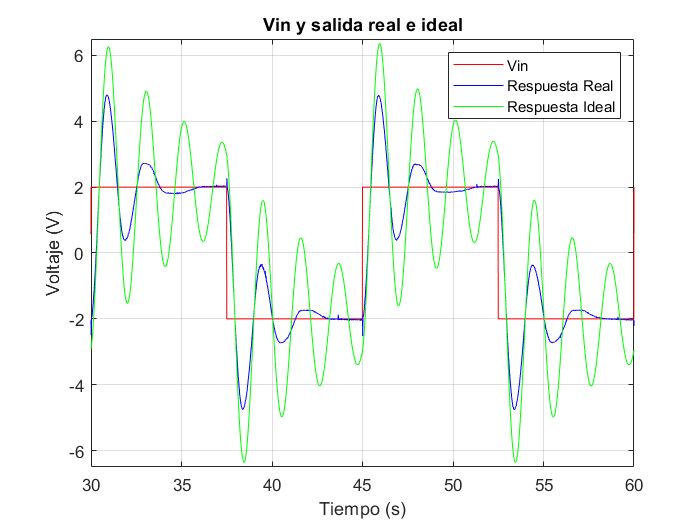

% Dibujar la respuesta del motor
if useExperimentalData
    % Usar Simulink
    addpath([pwd filesep 'PIvel']);
    open PID_experimental.slx;
    run PID_experimental.slx;
else
    FileName   = 'PID_real_ideal.mat';
    FolderName = [pwd filesep 'Common' filesep 'Resultados' filesep 'Prac3'];
    File       = fullfile(FolderName, FileName);
    load(File);   
end

figure
plot(PID_real_ideal.time,[PID_real_ideal.signals.values(:,1,:)],'r')
hold on; grid on;
plot(PID_real_ideal.time,[PID_real_ideal.signals.values(:,2,:)],'b')
plot(PID_real_ideal.time,[PID_real_ideal.signals.values(:,3,:)],'g')
xlim([30 60]); ylim([-6.5 6.5]);
xlabel('Tiempo (s)');
ylabel('Voltaje (V)');
title('Vin y salida real e ideal');
legend('Vin','Respuesta Real','Respuesta Ideal');

Como se puede observar, aunque el controlador sea capaz de establecer el sistema, las respuestas real e ideal no son parecidas. Esto ocurre porque uno de los polos se ha fijado libremente y aunque cumpla la metodología de ser libre y no dominante, esta afecta al sistema. Además de esto, el controlador añade dos ceros, los cuales también afectan a la dinámica del sistema. Junto a todo esto hay que añadir el efecto de que algunas dinámicas no han sido modeladas.

# Ejercicio 14: Diseñar los mismos controladores pero con el bloque PID de Simulink.

Saber como se diseñan y diseñar controladores PID es muy importante, ya que seremos capaces de realizar un lazo de control para cualquier sistema. Pero además de esto, tenemos que saber que MATLAB/Simulink ofrecen herramientas que simplifican nuestro trabajo. Por ejemplo, con la herramienta "*pidTuner*" podemos obtener las ganancias $k_p$,$\;k_i$ y $k_d$ teniendo solamente la función de transferencia de la planta y las especificaciones deseadas. Por otro lado, Simulink tiene un bloque especifico llamado "*PID Controller*" en el cual podemos especificar las ganancias de cada acción, coeficiente del filtro de la parte derivativa y el periodo de muestreo.

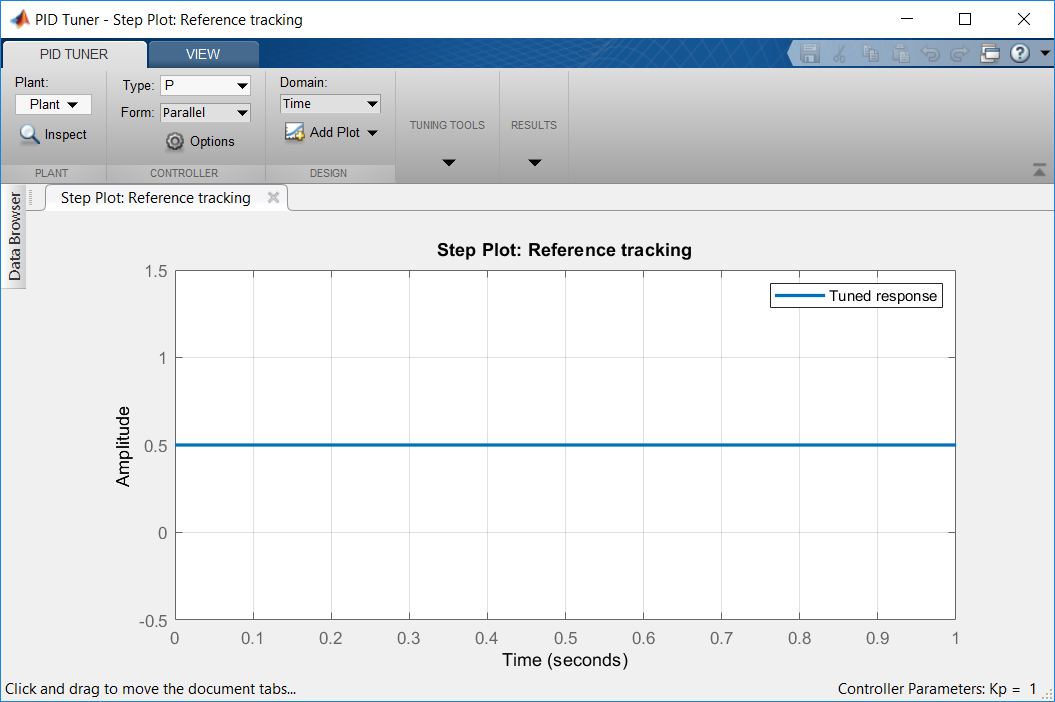

Figure 1: Herramienta pidTuner

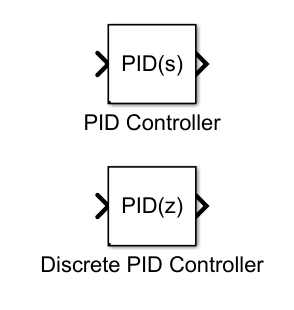

Figure 2: Bloques PID de Simulink

En este ejercicio se desea implementar los mismos controladores, pero usando este bloque especifico que ofrece Simulink. Para la simulación del PI abrir y ejecutar el modelo P3_Ex13a.slx. Para ejecutar este modelo en una planta abrir y ejecutar el modelo P3_Ex13b.slx. Para la simulación del PID, abrir y ejecutar el modelo P3_Ex13c.slx y para su comprobación usar el modelo P3_Ex13d.slx. Analizar que los resultados obtenidos en este ejercicio se asemejan a los resultados obtenidos en los ejercicios anteriores.